# 11/1

上半部有試著把他連出來了，但是下半部試不出一個可以增強信號又不會導致原本的圖連成一團的值。

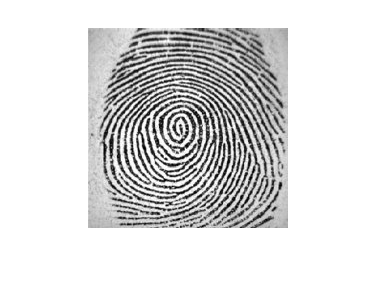

clear all;
I = imread('ori_1.jpg');
figure; imshow(I);

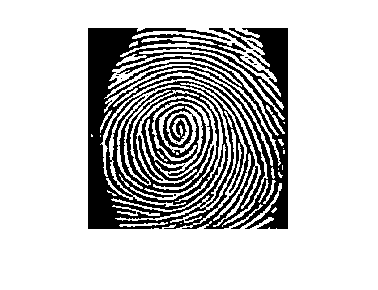

J = 1-(I(:,:,1)>150);
% B = [0 1 0; 1 1 1; 0 1 0];
se = strel("line", 3, 20);
se2 = strel("square", 2);
J1 = imclose(J(1:50,:), se);
J2 = imclose(J(151:200,:), se2);
output = vertcat(J1,J(50:150,:),J2); 
figure; imshow(output);

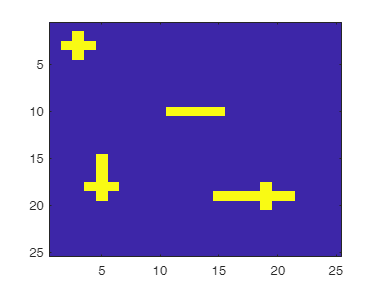

clear all;
I = imread("test.tiff");
imagesc(I);

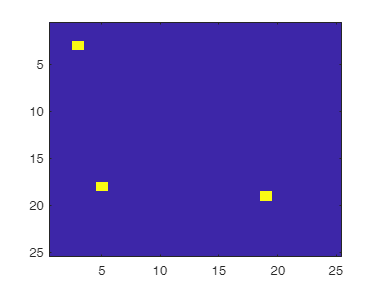

X = [0 1 0;1 1 1;0 1 0];
W = ones([3, 3]);
Y = W-X;
A = imerode(I, X) & imerode(imcomplement(I), Y);
imagesc(A);

中心：(310, 122), (196, 494), (210, 725), (685, 469), (1082, 469)

以下作法：

利用region filling填滿背景後反白

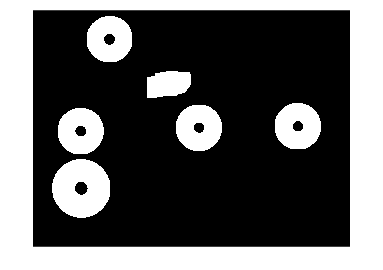

clear all;
I = imread("img_fill.png");
figure; imshow(I);

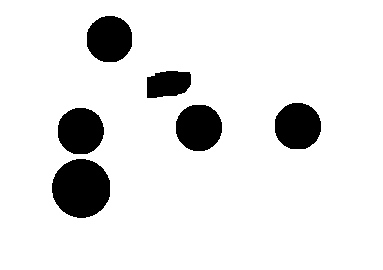

X = zeros(size(I), "uint8");
B = [0 1 0;1 1 1;0 1 0];
X(1,1) = 255;
while true
    Y = imdilate(X, B) & ~I;
    if X == Y
        break
    end
    X = Y;
end
figure; imshow(X); % Output

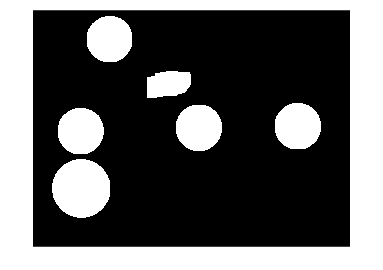

figure; imshow(~X);

原作法

clear all;
I = imread("img_fill.png");
figure; imshow(I);

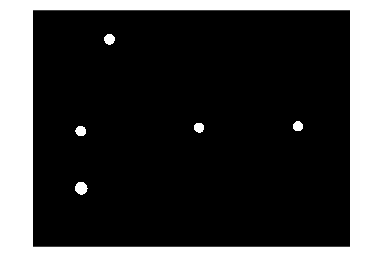

X = zeros(size(I), "uint8");
B = [0 1 0;1 1 1;0 1 0];
X(122, 310)=255;
X(494, 196)=255;
X(725, 210)=255;
X(469, 685)=255;
X(469, 1082)=255;
while true
    Y = imdilate(X, B) & ~I;
    if X == Y
        break
    end
    X = Y;
end
figure; imshow(X);

Output = I|X;
figure; imshow(Output); % Output